%{
ES115 - Class-Project Module: Water Tank Level Control
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-29

Purpose:
    - Simulate water tank level dynamics over time.
    - Model inflow and outflow rates with threshold-based control.
    - Observe steady-state or oscillatory behavior.

Input:
    - Time vector and simulation duration
    - Inflow rate (when valve is ON)
    - Outflow rate (constant drain)
    - Upper and lower level thresholds

Output:
    - Water level vs time plot
    - Threshold markers
    - Visualization of system stability

Engineering Algorithms:
    - Define time vector
    - Initialize tank level
    - Use time-stepping loop
    - Apply control logic:
        * Turn inflow ON when level is low
        * Turn inflow OFF when level is high
    - Update level using mass balance:
        Level = Level + (Inflow - Outflow)*dt
    - Prevent negative levels
    - Plot results with threshold lines

MATLAB tools/functions:
    - for loop
    - if statements
    - plot, yline
    - vector storage
    - figure
%}


clc; clear; close all;
% Clear environment

%Parameters

t = 0:0.1:100;     
% Time vector (seconds)

dt = 0.1;          
% Time step

N = length(t);     
% Number of time steps

%% Tank properties

level = zeros(1,N);  
% Preallocate water level array

level(1) = 5;        
% Initial water level (meters)

%% Flow rates

Q_in_max = 2;        
% Maximum inflow rate (m^3/s when valve ON)

Q_out = 1;           
% Constant outflow rate (drain)

%% Control thresholds

L_low = 3;           
% Lower threshold (turn inflow ON)

L_high = 8;          
% Upper threshold (turn inflow OFF)

valve_on = true;     
% Initial valve state (ON)


%Simulation Loop

for i = 1:N-1
    
    % Check lower threshold
    if level(i) <= L_low
        valve_on = true;     
        % Turn inflow ON if tank is too low
    end
    
    % Check upper threshold
    if level(i) >= L_high
        valve_on = false;    
        % Turn inflow OFF if tank is too high
    end
    
    % Determine inflow based on valve state
    if valve_on
        Q_in = Q_in_max;     
        % Full inflow when valve ON
    else
        Q_in = 0;            
        % No inflow when valve OFF
    end
    
    % Mass balance equation
    dL = (Q_in - Q_out) * dt;  
    % Change in water level
    
    level(i+1) = level(i) + dL;  
    % Update water level
    
    % Prevent negative water level
    if level(i+1) < 0
        level(i+1) = 0;
    end
    
end

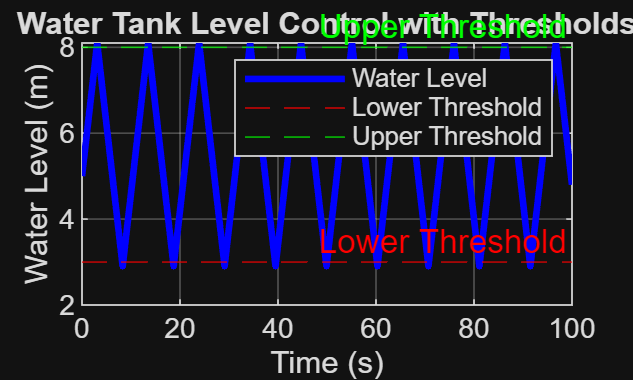

%Plotting

figure;

plot(t, level, 'b', 'LineWidth', 2)
% Plot water level vs time

hold on

yline(L_low, '--r', 'Lower Threshold')
% Plot lower threshold line

yline(L_high, '--g', 'Upper Threshold')
% Plot upper threshold line

xlabel('Time (s)')
ylabel('Water Level (m)')
title('Water Tank Level Control with Thresholds')
legend('Water Level', 'Lower Threshold', 'Upper Threshold')
grid on

%Analysis Output

disp('Simulation complete.')

Simulation complete.



% Compute average level
avg_level = mean(level);

disp(['Average water level: ', num2str(avg_level)])

Average water level: 5.5632
